**Lab 2: Probability, Distributions, and Statistical Questions**

**Problem 1**

I will assume that in 1 day, the average cosmic-ray background is 3, and the number of gamma-rays emitted by my sample is 4.2. 

*A) Show how the probability distribution changes as you integrate for more days.*

First, I want to setup the probability distribution for 1 day.

lambda = 3;
pDist1day = makedist("Poisson","lambda",lambda);

Next, I want to account for multiple days, so I will multiply the range and the lambda of the distribution by N, where N is the number of days.

N = 5; %choice to be specified later on
lambdaN = lambda*N;
x = 0:20;%vector of x inputs
x1 = 0:(20*N);
pdfPDist1day = pdf(pDist1day,x);
pDistNdays = makedist("Poisson","lambda",lambdaN)

pDistNdays =   PoissonDistribution

  Poisson distribution
    lambda = 15


pdfPDistNdays = pdf(pDistNdays,x1);

pdfPDistNdays is now the probability density function for N days.

We can now compare the pdfs for 1 day and N days, varying N, and see how they change.

subplot(3,1,1);
plot(x,pdfPDist1day);
title('pdf for 1 day');
subplot(3,1,2);
plot(x1,pdfPDistNdays);
name = strcat('pdf for ',num2str(N),' days');
title(name);

Change N to be 12 days.

N = 12;
lambdaN = lambda*N;
pDistNdays = makedist("Poisson","lambda",lambdaN)

pDistNdays =   PoissonDistribution

  Poisson distribution
    lambda = 36


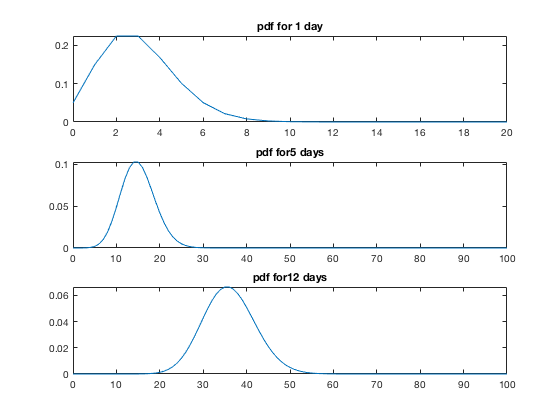

pdfPDistNdays = pdf(pDistNdays,x1);
subplot(3,1,3);
plot(x1,pdfPDistNdays);
name = strcat('pdf for ',num2str(N),' days');
title(name);

Let's look at them in a log y-scale as well.

figure;
subplot(3,1,1);
plot(x,pdfPDist1day);
set(gca,'YScale','log');
title('pdf for 1 day log plot');
subplot(3,1,2);
N = 5;
lambdaN = lambda*N;
pDistNdays = makedist("Poisson","lambda",lambdaN)

pDistNdays =   PoissonDistribution

  Poisson distribution
    lambda = 15


pdfPDistNdays = pdf(pDistNdays,x1);
plot(x1,pdfPDistNdays);
set(gca,'YScale','log');
name = strcat('pdf for ',num2str(N),' days log plot');
title(name);
subplot(3,1,3);
N = 12;
lambdaN = lambda*N;
pDistNdays = makedist("Poisson","lambda",lambdaN)

pDistNdays =   PoissonDistribution

  Poisson distribution
    lambda = 36


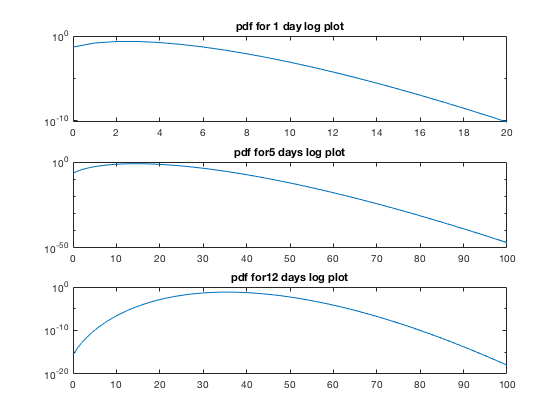

pdfPDistNdays = pdf(pDistNdays,x1);
plot(x1,pdfPDistNdays);
set(gca,'YScale','log');
name = strcat('pdf for ',num2str(N),' days log plot');
title(name);

Although the changes on the log scale may not be very noticeable, they would be if we drastically increased the number of days.

We can see that changing the number of days spreads the distribution out. The total integral of the distribution is still limited to 1, as it is a probability distribution, but now integrating up to a certain value on both distributions will give different results as they will encapsulate different areas.

*B) Show that after 5 days, the summed probability distribution is still a Poisson distribution. Explain why this makes sense from a mathematical and conceptual point of view.*

First, reproduce the pdf with N = 5 days.

N = 5;%setting the number of days
lambdaN = lambda*N;
pDistNdays = makedist("Poisson","lambda",lambdaN)

pDistNdays =   PoissonDistribution

  Poisson distribution
    lambda = 15


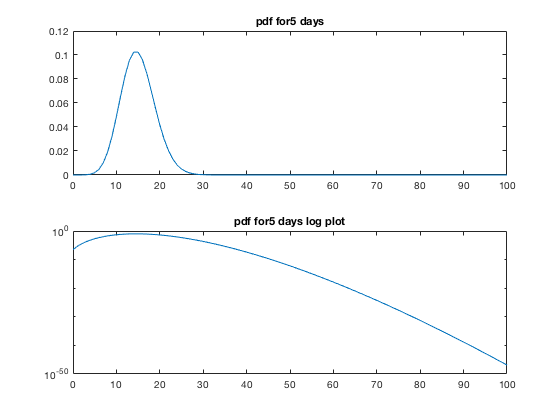

pdfPDistNdays = pdf(pDistNdays,x1);
figure;
subplot(2,1,1);
plot(x1,pdfPDistNdays);
name = strcat('pdf for ',num2str(N),' days');
title(name);
subplot(2,1,2);
plot(x1,pdfPDistNdays);
set(gca,'YScale','log');
name = strcat(name,' log plot');
title(name);

In order to check that these are indeed still Poisson distributions, we can check by doing a convolution of the original Poisson distribution for 1 day with itself N times.

pdfCheck = conv(pdfPDist1day,pdfPDist1day);
for i = 1:(N-2)
    pdfCheck = conv(pdfCheck,pdfPDist1day);
end
x = 0:100;

Compare plots side by side.

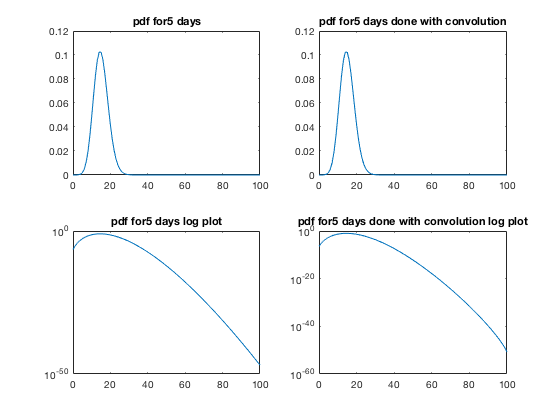

figure;
subplot(2,2,1);
plot(x1,pdfPDistNdays);
name = strcat('pdf for ',num2str(N),' days');
title(name);
subplot(2,2,2);
plot(x,pdfCheck);
name1 = strcat(name,' done with convolution');
title(name1);
subplot(2,2,3);
plot(x1,pdfPDistNdays);
set(gca,'YScale','log');
title(strcat(name,' log plot'));
subplot(2,2,4);
plot(x,pdfCheck);
set(gca,'YScale','log');
title(strcat(name1,' log plot'));

These look identically the same. This makes sense because when we're changing the range and the "mean" of the distribution by multiplication, we are essentially saying "what if I were to repeat this measurement N number of times." The convolution calculates the sum of the probabilities over all possible offsets, and since I've convolved it N times, the two are identical.

*C) Show how the probability distribution evolves as you average days. Calculate for many different ranges of days, and explore the shape of the distribution as the number of days becomes larger. Discuss this in relation to both B) and the central limit theorem.*

Divide the range of x after the convolution by the number of convolutions (days), so now instead of the range of x being 0:20, it will be 0:10 with the same number of steps.

Check average for N = 5, 10, 100 days.

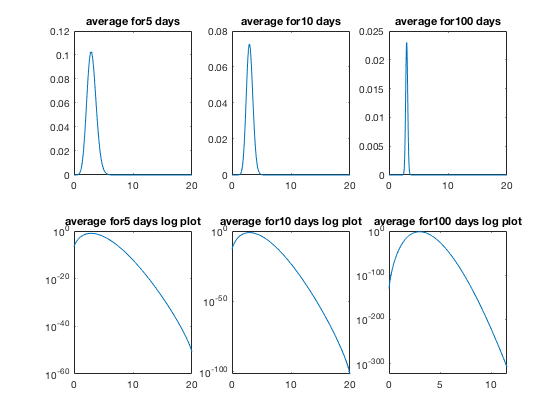

xN = x./N;
figure;
subplot(2,3,1);
plot(xN,pdfCheck);
name = strcat('average for ',num2str(N),' days');
title(name);
subplot(2,3,4);
plot(xN,pdfCheck);
set(gca,'YScale','log');
title(strcat(name,' log plot'));
N = 10;
pdfCheck = conv(pdfPDist1day,pdfPDist1day);
for i = 1:(N-2)
    pdfCheck = conv(pdfCheck,pdfPDist1day);
end
x = 0:200;
xN = x./N;
subplot(2,3,2);
plot(xN,pdfCheck);
name = strcat('average for ',num2str(N),' days');
title(name);
subplot(2,3,5);
plot(xN,pdfCheck);
set(gca,'YScale','log');
title(strcat(name,' log plot'));
N = 100;
pdfCheck = conv(pdfPDist1day,pdfPDist1day);
for i = 1:(N-2)
    pdfCheck = conv(pdfCheck,pdfPDist1day);
end
x = 0:2000;
xN = x./N;
subplot(2,3,3);
plot(xN,pdfCheck);
name = strcat('average for ',num2str(N),' days');
title(name);
subplot(2,3,6);
plot(xN,pdfCheck);
set(gca,'YScale','log');
title(strcat(name,' log plot'));

If we were to not compress the x-axis, then the mean value would increase, thus approaching a distribution that can be very well approximated by a Gaussian. However, since we're squashing the axes, as we increase the number of days over which the sampling is averaged, we are simply making the distribution more and more sharply peaked.

*D) Pick some number of days N, and assume you saw Y*N gamma rays from your source. Calculate the 'sigma' of your observation.*

Set up the distribution.

Y = 4.2;
N = 23;%Calculate for N = 23 days
lambdaN = lambda*N;
pDistNdays = makedist("Poisson","lambda",lambdaN)

pDistNdays =   PoissonDistribution

  Poisson distribution
    lambda = 69


pdfCheck = conv(pdfPDist1day,pdfPDist1day);
for i = 1:(N-2)
    pdfCheck = conv(pdfCheck,pdfPDist1day);
end
x = 0:460;
xN = x./N;

Evaluate the integral of the distribution from the right until Y*N

prob = 1 - cdf(pDistNdays,Y*N)

prob = 8.4554e-04

Find sigma by equating the probability to the result of a normal distribution.

sigma = icdf('Normal',1-prob,0,1)

sigma = 3.1397

Calculated sigma is ~3.1397.

**Problem 2**

*A) Show how the distribution changes as you average over more observing intervals.*

Setup the Rayleigh distribution over 1 interval.

ray = makedist('Rayleigh',"b",1.3);
x = 0:20;
rayPDF = pdf(ray,x);

Choose number of intervals. I will explore N = 1, 10, 18.

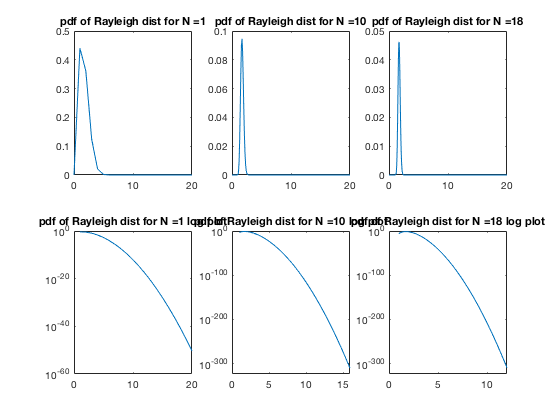

N = 1;%number of intervals, trivial for N = 1
figure;
subplot(2,3,1);
plot(x,rayPDF);
name = strcat('pdf of Rayleigh dist for N = ',num2str(N));
title(name);
subplot(2,3,4);
plot(x,rayPDF);
set(gca,'YScale','log');
title(strcat(name,' log plot'));
N = 10;
rayPDFN = conv(rayPDF,rayPDF);
for i = 1:(N-2)
    rayPDFN = conv(rayPDFN,rayPDF);
end
x = 0:200;
xN = x./N;
subplot(2,3,2);
plot(xN,rayPDFN);
name = strcat('pdf of Rayleigh dist for N = ',num2str(N));
title(name);
subplot(2,3,5);
plot(xN,rayPDFN);
set(gca,'YScale','log');
title(strcat(name,' log plot'));
N = 18;
rayPDFN = conv(rayPDF,rayPDF);
for i = 1:(N-2)
    rayPDFN = conv(rayPDFN,rayPDF);
end
x = 0:360;
xN = x./N;
subplot(2,3,3);
plot(xN,rayPDFN);
name = strcat('pdf of Rayleigh dist for N = ',num2str(N));
title(name);
subplot(2,3,6);
plot(xN,rayPDFN);
set(gca,'YScale','log');
title(strcat(name,' log plot'));

As we average over more intervals, the distribution becomes more and more sharp.

*B) Discuss how the shape changes. Does it approach a Gaussian distribution? If yes, after how many intervals?*

As briefly mentioned above, the distribution becomes sharper as we average over more intervals. The distribution also seems to approach a more symmetric shape, vs the skewed shape that can be seen for N=1 (top left plot) in previous figure.

I believe that the distribution does in fact approach a Gaussian (or can be approximated by a Gaussian). It looks semi-Gaussian for N = 18, but I can test higher values of N to see if it is more clearly a Gaussian.

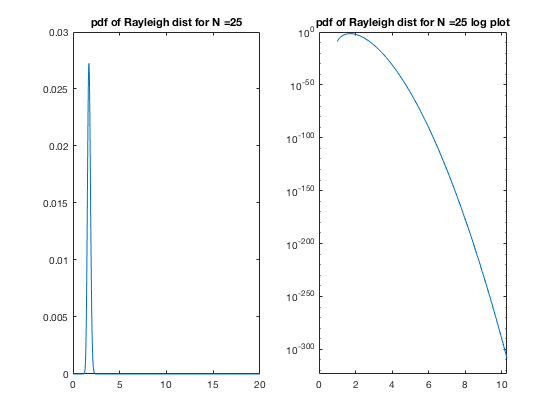

N = 25;
rayPDFN = conv(rayPDF,rayPDF);
for i = 1:(N-2)
    rayPDFN = conv(rayPDFN,rayPDF);
end
x = 0:500;
xN = x./N;
figure;
subplot(1,2,1);
plot(xN,rayPDFN);
name = strcat('pdf of Rayleigh dist for N = ',num2str(N));
title(name);
subplot(1,2,2);
plot(xN,rayPDFN);
set(gca,'YScale','log');
title(strcat(name,' log plot'));

To be honest, I don't think this looks "more Gaussian" than N = 18, so I'll say it approaches a Gaussian distribution after about 15 intervals. This is an estimate.

**Problem 3**

**Version 1**

*A) Calculate the significance of your detection. Can you claim a discovery?*

Wow, lots of assumptions to make here. I will assume a thickness of 3, and a signal strength of 5.36.

background = makedist('Normal',"mu",0,"sigma",3);
signal = 5.36;

Integrate the background distribution from the right to the signal value to obtain probability that the signal is not produced by the background distribution.

prob = 1 - cdf(background,signal)

prob = 0.0370

Convert the probability into sigma.

sigma2 = icdf('Normal',1-prob,0,1)

sigma2 = 1.7867

The obtained sigma is ~1.79, which does not qualify as a "significant" discovery, as it is less than 5.

**Version 2**

*B) If you have to look for a signal in 10k pixels, what is the probability distribution of your background? (Clearly state the statistical question, then turn that into math using your background distribution from part 1 of this problem).*

What is the background probability distribution of 10k pixels, given the background probability distribution of 1 pixel?

We want to scale the individual distribution per pixel by 10000, since each individual pixel has the same type of probability distribution. This should be identical to convolving and averaging 9999 times.

xVec = -10:10;%have to choose a small vector so that the 
%convolution behaves well (too many iterations otherwise)
backgroundPDF = pdf(background,xVec);
backgroundFull = conv(backgroundPDF,backgroundPDF);
M = 10000;
for i = 1:(M-2)
    backgroundFull = conv(backgroundFull,backgroundPDF);
end
x = -100000:100000;
xM = x./M;

This gives a normalized probability distribution for the 10000 pixels. I will also create a distribution (not normalized) for the 10000 pixels by simply multiplying the pdf of the 1 pixel background. 

numPixels = 10000;
backgroundFull2 = backgroundPDF * numPixels;

Plot the background in both cases to see what they look like.

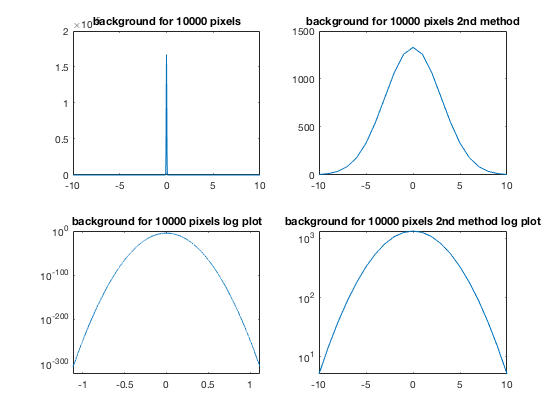

figure;
subplot(2,2,1);
plot(xM,backgroundFull);
name = 'background for 10000 pixels';
title(name);
subplot(2,2,3);
plot(xM,backgroundFull);
set(gca,'YScale','log');
title(strcat(name,' log plot'));
subplot(2,2,2);
plot(xVec,backgroundFull2);
title(strcat(name,' 2nd method'));
subplot(2,2,4);
plot(xVec,backgroundFull2);
set(gca,'YScale','log');
title(strcat(name,' 2nd method log plot'));

The distribution for multiplication by 10k looks a bit choppy since I chose such a small x vector (in order to make convolutions work), so I will redo it with a better x vector.

xVec2 = -500:500;
backgroundPDF = pdf(background,xVec2);
backgroundFull2 = backgroundPDF * numPixels;

Replot the same plots.

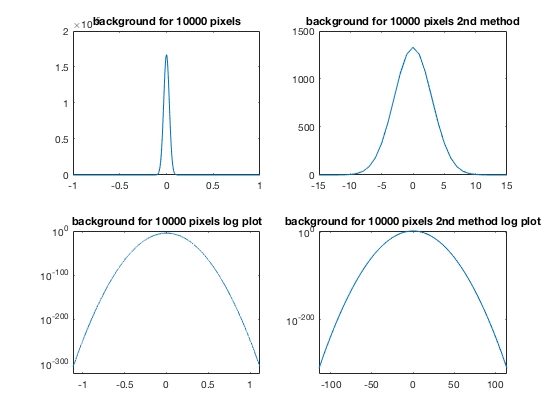

figure;
subplot(2,2,1);
plot(xM,backgroundFull);
name = 'background for 10000 pixels';
xlim([-1 1])
title(name);
subplot(2,2,3);
plot(xM,backgroundFull);
set(gca,'YScale','log');
title(strcat(name,' log plot'));
subplot(2,2,2);
plot(xVec2,backgroundFull2);
title(strcat(name,' 2nd method'));
xlim([-15 15]);%otherwise the plot looks like a delta function
subplot(2,2,4);
plot(xVec2,backgroundFull2);
set(gca,'YScale','log');
title(strcat(name,' 2nd method log plot'));

It still looks choppy, so I am suspecting that it is a result of the direct multiplication by a large trials factor.

*C) Taking your brightest candidate signal from the region (assume it has the same signal as in part 1), calculate the significance of your detection.*

Signal defined in part 1 was 5.36. Integrate this on the probability distribution over 10000 pixels, and then convert the probability to sigma on a normal distribution.

This is actually a bit more complicated than I thought. Conv() takes vectors as inputs, but in order for me to use cdf and icdf, I need to use probability distribution functions. That means I need to figure out a way to recreate a probability distribution function with parameters that would be equal to the results of a convolution of a Gaussian X times (10k in this case).

Convolution of a Gaussian with mu = mu_i and sigma^2 = sigma_i^2 is approximated by a Gaussian with mu = sum(mu_i) and sigma^2 = sum(sigma_i ^2). Mu will not change because it's 0 originally, but I've set sigma = 3, so sigma^2 = 9. Now I must sum that X times and recreate the Gaussian with the new parameters.

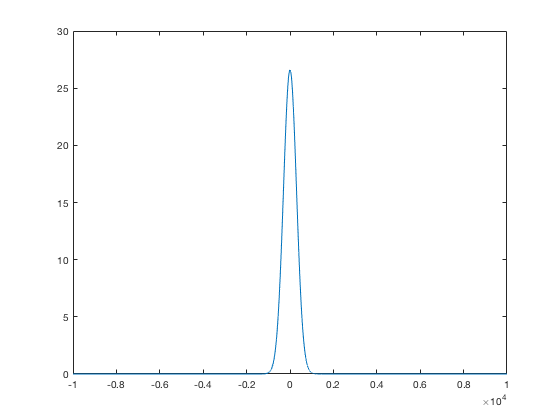

xVec2 = -10000:10000;
sigmaNew = sqrt(9*M);
backgroundConvolved = makedist('Normal','mu',0,'sigma',sigmaNew);
% xVec2 = xVec2./M;
backgroundConvPDF = pdf(backgroundConvolved,xVec2);
normalization = sum(backgroundConvPDF)/length(xVec2);
backgroundConvPDF = backgroundConvPDF./normalization;
figure;
plot(xVec2,backgroundConvPDF);

test = fitdist(backgroundConvPDF','Normal');
% [mutest,sigmatest,muCItest,sigmaCItest] = normfit(backgroundConvPDF)
probConv = 1- cdf(test,signal)

probConv = 0.1508

sigma3 = icdf('Normal',1 - probConv,0,1)

sigma3 = 1.0332

probConv = 1 - cdf(test,19.6657);
sigma4 = icdf('Normal',1 - probConv,0,1)

sigma4 = 4.4232

I honestly have no idea how to get this part to work. I am unsure how to integrate a vector on certain bounds, and recreating a Gaussian with the "new" parameters seems to be giving really weird values for the probability and the sigma. This makes sense, because the sigma that is used to define this new Gaussian is 300 according to the analytical method, which is too large. I would normally need to renormalize the PDF, but I cannot do that due to it being a probability distribution object.

I think that my approximation with renormalizing the background PDF and fitting it with a normal distribution gives values that are approximately correct. The distribution looks good, and the sigma for 19.6657 (value found in prob 4 part B) kind of makes sense, although I would have expected it to be closer to 5.

**Problem 4**

*A) Calculate the signal required for a 5-sigma detection in Version 1*

I will be using the same background as setup in problem 3.

Since we know the probability that is associated with 5 sigma, we can integrate the background distribution until we obtain that probability.

probSigma = 1/(3.6e6);%~1 in 3.6 million is 5 sigma
threshold1 = icdf(background,1 - probSigma)

threshold1 = 15.0182

*B) Calculate the signal required for a 5-sigma detection in Version 2*

threshold2 = icdf(background,1 - (probSigma/numPixels))

threshold2 = 19.6657

*C) Discuss how much brighter the signal must be for discovery if you have a trials factor of 10k. Looking at your probability distributions, explain why the sensitivity penalty due to a trials factor is so low.*

threshold2-threshold1

ans = 4.6475

Threshold1 is ~15.02, while threshold2 is ~19.67, which are not that vastly different. The penalty is this low because although the trial factor may be large, a normal distribution falls of very quickly. This implies that the results of the integration will fall of rather quickly also, meaning that the two thresholds would be not too dissimilar.

*D) If you changed the trials factor significantly (orders of magnitude), how large is the effect on your 5-sigma sensitivity threshold?*

I think changing the trials factor by a few orders of magnitude would not have a large effect on the 5-sigma sensitivity threshold. I will check for 10 million pixels (increasing by 2 orders), and 1 billion (increasing by 4 orders).

numPixels = 1000000;
threshold3 = icdf(background,1 - (probSigma/numPixels))
numPixels = 100000000;

threshold3 = 21.6329

threshold4 = icdf(background,1 - (probSigma/numPixels))

threshold4 = 23.4412

As seen, the thresholds did not change very significantly.

*Extra credit: If you had a different distribution shape (non-Gaussian), how would that affect the sensitivity penalty of many trials? Clearly explain.*

According to the central limit theorem, the distributions will be approximated by a Gaussian as the number of trials is increased, so the sensitivity penalty would behave similarly to the case explored in problem 4.